# $\epsilon(z)$ synthesis from $\Gamma(\omega, z)$

Assume we work in odd mode

The line is as follows

- L = 200 $\mu$

- 
$$Z_L = 70 + j\omega 3\times10^9 \Omega$$


- 
$$R_g=50 \Omega$$


- W = S = 20 $\mu$

- 
$$L_{strip} = 3 \mu$$


- 
$$S_{strip} = 1\mu$$


- 
$$W_{strip} = 30\mu$$


clear all;
mu0 = 4*pi*1e-7;  % Value of mu_0 in N/A^2 (Tm/A)
epsilon0 = 8.8541878128e-12;  % Value of epsilon_0 in F/m
L = 200e-6;
W = 20e-6;
S = W;
Lstrip = 3e-6;
Sstrip = 1e-6;
Wstrip = 30e-6;

Rg = 50; % omega

coupledmicrostrip = coupledMicrostripLine(Length=200e-6, ...
                                            Width=20e-6, ...
                                            Spacing=20e-6, ...
                                            Height = 10e-6, ...
                                            GroundPlaneWidth=200e-6 ...
                                         )

coupledmicrostrip =   coupledMicrostripLine with properties:

              Length: 2.0000e-04
               Width: 2.0000e-05
             Spacing: 2.0000e-05
              Height: 1.0000e-05
    GroundPlaneWidth: 2.0000e-04
           Substrate: [1×1 dielectric]
           Conductor: [1×1 metal]


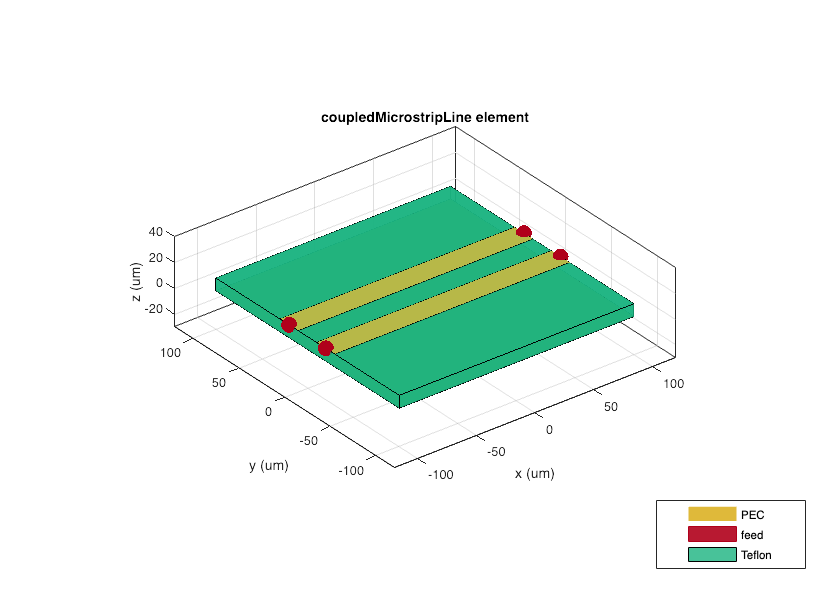

show(coupledmicrostrip)

### Calculating charactaristics of Transmission Line

From Pozar:

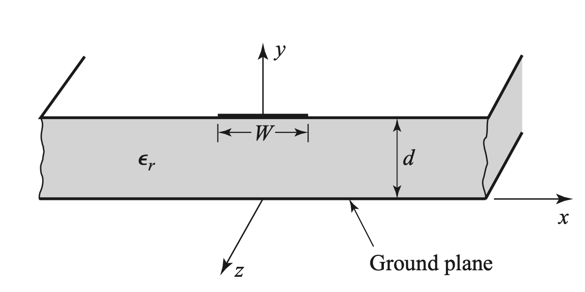

Effective Dielectric: $\epsilon_e=\frac{\epsilon_r+1}{2} + \frac{\epsilon_r-1}{2}\frac{1}{\sqrt{1+12d/W}}$

We have


$$\Gamma(\omega, z)=\frac{Z_L-Z(\omega, z)}{Z_L+Z(\omega,z)}$$


We also want that $Z(\omega, L) = Z_L$

Assume we are given that $\Gamma(\omega, z)\Big|_{z=0}$ is a low pass chebyshev's filter

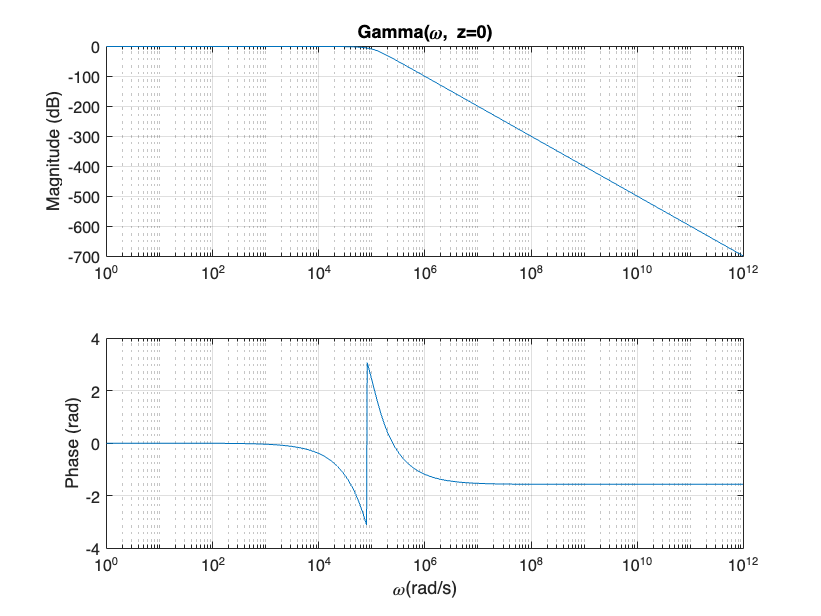

[b,a] = besself(5,1e5);
[Gamma0,w] = freqs(b,a,logspace(0, 12, 1e3));
figure;
plot_resp_logy(w, Gamma0, 'Gamma(\omega, z=0)')

Now that $\omega$ is defined, we can define $Z_L$

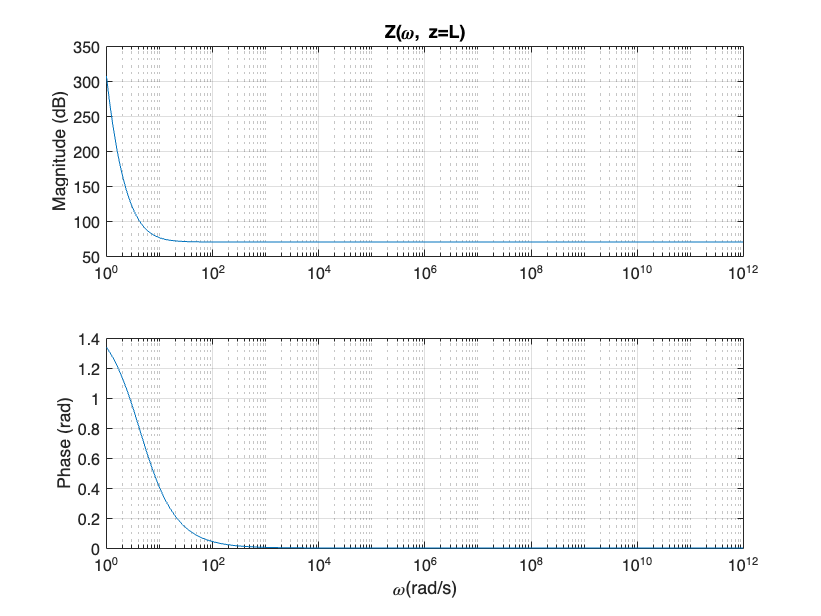

ZL = 70 + 3e2*1j./w;
figure;
plot_resp(w, ZL, 'Z(\omega, z=L)')

`Using `$\Gamma(\omega, 0)$`, we can find `$Z(\omega, 0)$` given by Z0`


$$\Gamma(\omega, 0)=\frac{R_g-Z(\omega, 0)}{R_g+Z(\omega,0)}\to  Z(\omega, 0)=R_g\frac{1-\Gamma(\omega, 0)}{1+\Gamma(\omega, 0)}$$
 

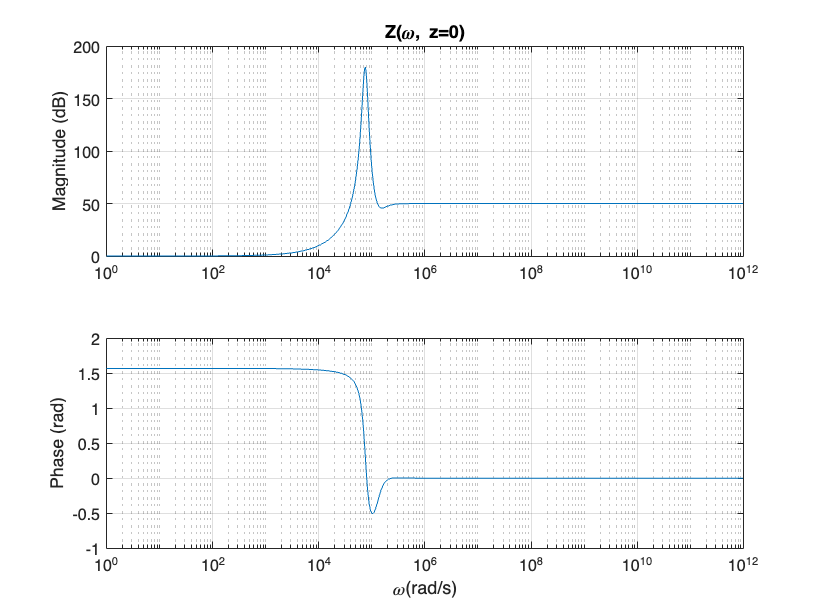

Z0 = Rg.*((1-Gamma0)./(1+Gamma0));
figure;
plot_resp(w, Z0, 'Z(\omega, z=0)')

fprintf("rad(Z0) = [%d, %d]", min(angle(Z0)), max(angle(Z0)));

rad(Z0) = [-5.075128e-01, 1.570794e+00]

**Task** : to synthesize $Z(\omega, z)$ and thus $\epsilon(\omega, z)$ across the line

**Idea**

- Divide the transmission line into N parts of length l each, where l = Lstrip+Sstrip

- Thus, is each part, we have a uniform transmission line

- So look at the transmission line we have as a collection of N transmission lines, each having unform charactaristic impedance.

- Since we can have the switch either closed or open, we have only two possible values of charactaristic impedances Zc and Zo (closed and open)

- We find each of the two, which are same for all the parts in the line

- For each of the small TL, we have two possible S parameters. We find these parameters and thus find reflection coeffcient at the end of the small TL

- Weigted averge around interested frequency and choose the min value. The Z which gives the min value is the chosen Z for that small TL

N = 8; % number of elements
l = L/N

l = 2.5000e-05

We iterate across the elements of transmission line

choice_arr = zeros(1, N);
epsz = zeros(1, N);

curr_Gamma0 = Gamma0;
num_pts = 1e2;

Gamma_element_on = zeros(num_pts, length(Gamma0));
Gamma_element_off = zeros(num_pts, length(Gamma0));

for i = 1:N
    [Beta_on, Beta_off, alpha_on, alpha_off] = find_Beta(w, epsilon0, mu0);
    Gamma_element_on = synthesize_Gamma_of_element(curr_Gamma0, alpha_on, Beta_on, l, num_pts, Gamma_element_on);
    Gamma_element_off = synthesize_Gamma_of_element(curr_Gamma0, alpha_off, Beta_off, l, num_pts, Gamma_element_off);
    [choice, d_on, d_off, next_Gamma0] = choose_switch_for_element(Gamma_element_on, Gamma_element_off, curr_Gamma0); % choose which ever is closer to the og
    %Gamma_element_on == Gamma_element_off;
    %figure;
    %plot_switch_comparison(w, Gamma0, Gamma_element_on(50, :), Gamma_element_off(50, :));
    curr_Gamma0 = next_Gamma0;
    choice_arr(i) = choice;
end

Plot Necessary switch positions

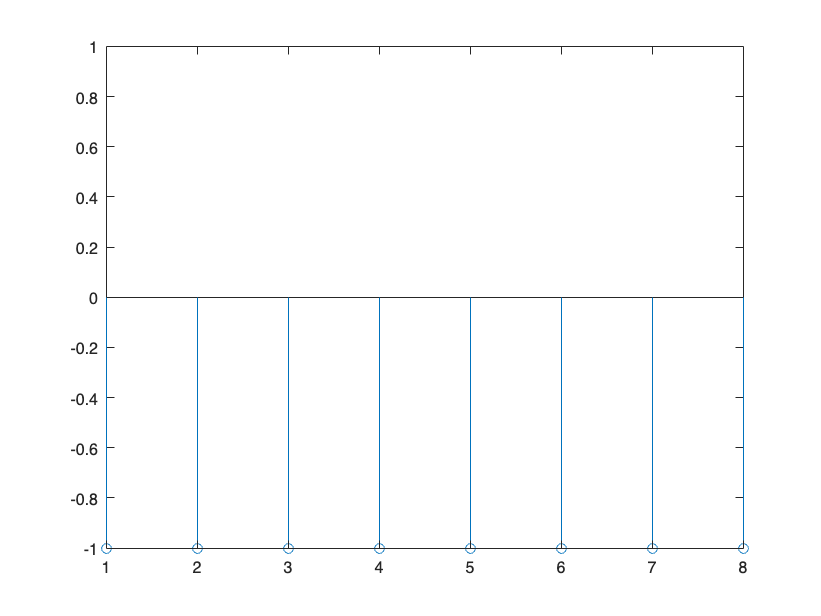

figure
stem(1:length(choice_arr), choice_arr)
ylim([-1, 1])

### Necessary Functions

function plot_resp_logy(x, y, name) % plot functions with dB in y
    subplot(2, 1, 1)
    semilogx(x, 20*log(abs(y))/log(10))
    title(name)
    ylabel("Magnitude (dB)")
    grid("on")
    subplot(2, 1, 2)
    semilogx(x, angle(y))
    ylabel("Phase (rad)")
    xlabel("\omega(rad/s)")
    grid("on")
end

function plot_resp(x, y, name) % plot functions
    subplot(2, 1, 1)
    semilogx(x, abs(y))
    title(name)
    ylabel("Magnitude (dB)")
    grid("on")
    subplot(2, 1, 2)
    semilogx(x, angle(y))
    ylabel("Phase (rad)")
    xlabel("\omega(rad/s)")
    grid("on")
end

function plot_switch_comparison(w, Gamma0, Gamma_on, Gamma_off)
    subplot(3, 1, 1)
    semilogx(w, 20*log(abs(Gamma0))/log(10))
    ylabel("\Gamma(\omega, z=0)")
    grid("on")
    subplot(3, 1, 2)
    semilogx(w, 20*log(abs(Gamma_on))/log(10))
    ylabel("\Gamma_{on}(\omega)")
    grid("on")
    subplot(3, 1, 3)
    semilogx(w, 20*log(abs(Gamma_off))/log(10))
    ylabel("\Gamma_{off}(\omega)")
    grid("on")
    xlabel("\omega(rad/s)")
end

function [Beta_on, Beta_off, alpha_on, alpha_off] = find_Beta(w, epsilon0, mu0) % finds the value of Beta_on
    % Beta = w*sqrt(L*C) where L and C are per unit length
    Beta_on = w.*sqrt(30*epsilon0*mu0);
    Beta_off = w.*sqrt(epsilon0*mu0);
    alpha_on = Beta_on;
    alpha_off = Beta_off;
end

function Gamma_element = synthesize_Gamma_of_element(Gamma0, alpha, Beta, l, num_pts, Gamma_element) % find Gamma across a element when switch in on
    z = linspace(0, l, num_pts); % z across the length of the element
    for i = 1:num_pts
        Gamma_element(i, :) = Gamma0.*exp(2.*(alpha + 1j.*Beta).*z(i));
    end
end

function [choice, d_on, d_off, next_Gamma0] = choose_switch_for_element(Gamma_element_on, Gamma_element_off, Gamma0) % chooses the optimal value of Gamma and returns the Gamm0 for next element
    d_on = 0; d_off = 0;
    for i = 1:length(Gamma_element_on(:, 1))
        d_on = d_on + compute_dist_between_arr(Gamma_element_on(i, : ), Gamma0);
        d_off = d_off + compute_dist_between_arr(Gamma_element_off(i, : ), Gamma0);
    end
    if (d_on <= d_off)
        choice = 1;
    else
        choice = -1;
    end
   %next_Gamma0 = zeros(1, length(Gamma0));
    next_Gamma0 = Gamma_element_on(length(Gamma_element_on(:, 1)), :);
end

function d = compute_dist_between_arr(x, y)
    darr = abs(x-y);
    d = sum(darr);
end